clc

addpath("c:/git/UQ4PDE_Homeworks/Homework 2/sobol package/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 2/functions/")

For given $h>0$ and $\theta>0$, approximate $\mathbb{E}[\exp(-\theta Q(u))]$ by


$$\mathbb{E}[\exp(-\theta Q(u))]\approx\frac{1}{M}\sum_{i=1}^M \exp(-\theta Q(u_h^{(i)}))$$


where $u_h^{(i)}$, $i=1,\ldots,M$, are iid realizations of $u_h$.

nu = 0.5;
M = 100000;
I = 8;
theta = linspace(0.1, 1, 100);
X = [20];
P_bound = zeros(1, M);
for m=progress(10000:10000:M)
    [P_bound(m), max_theta(m)] = chernoff_task(nu, m, theta, I, X);
end

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]


%[P_bound, max_theta] = chernoff_task(nu, M, theta, I, X);


[P, t] = max(P_bound(10000:10000:M))

P = 0.0131

t = 5

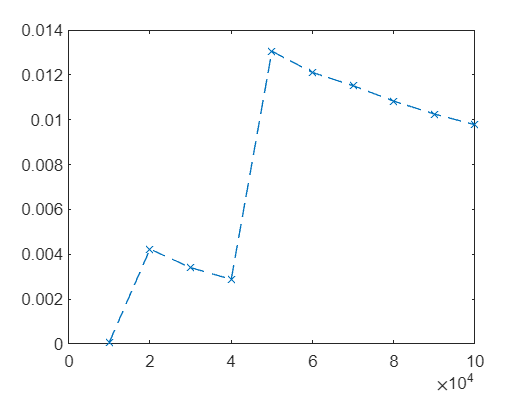


plot(10000:10000:M, P_bound(10000:10000:M), 'x--')